% Copyright (C) Andrea Vedaldi and Andrew Zisserman
%
% The purpose of this exercise is to observe different building-blocks of
% Convolutional Neural Networks (CNN), and use Stochastic Gradient Descent 
% (SGD) to train a CNN.
%
% Fill any required parts with your own code, and answer any questions
% asked in each section.

## Run setup before continuing

Use ctrl+Enter (or click 'Run Section') to run each section separately

setup ;

## Example image

Read an example image

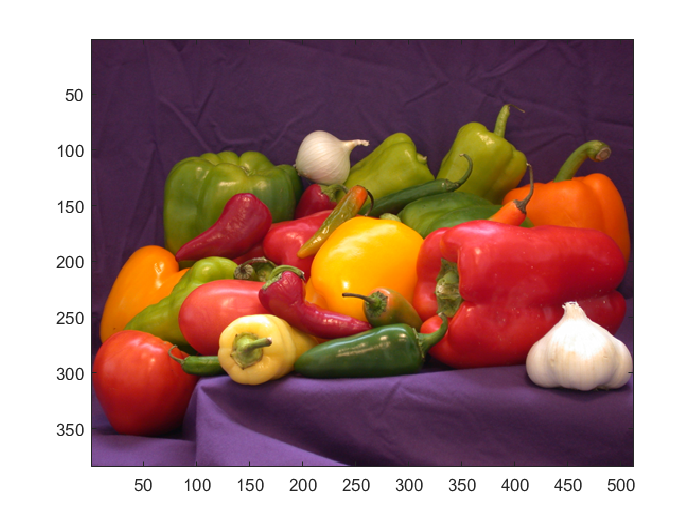

x = imread('peppers.png') ;

% Convert to single format for MatConvNet
x = im2single(x) ;

% Visualize the input x
figure(1) ; clf ; imagesc(x) ;


% Your task: Use MATLAB's 'size' function to display the size of x.
%            What is the size of third dimension and why?


## Your code starts here %%%

size(x)

ans =    384   512     3


The size of the third dimension of x is 3.

## Your code stops here %%%

## Creating a filter bank

Create a bank of 10 linear filters with size 5x5x3

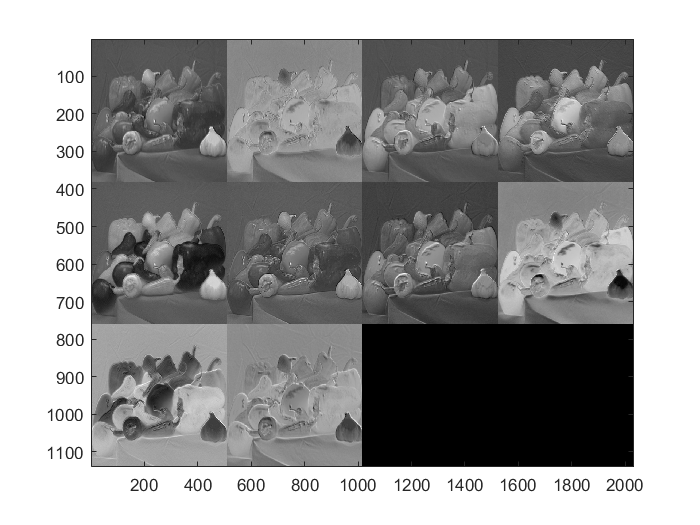

w = randn(5,5,3,10,'single') ;  % again, single precision

% Apply the convolutional operator
y = vl_nnconv(x, w, []) ;  % the 3rd argument here is a vector of bias terms (empty in our case)

% Visualize the output y
figure(2) ; clf ; vl_imarraysc(y) ; colormap gray ;


% Try running this section a few times. 

% Your task: Is there any difference between each run? Why?
%           The reason is the contrast and illumination. As the grey parts of the picture
%           are increasingly dark
size(y)

ans =    380   508    10


%            What is the size of the output y, and how is this related to
%            x and w?
%            The size is 10             

## Applying downsampling and padding

Try again, downsampling the output

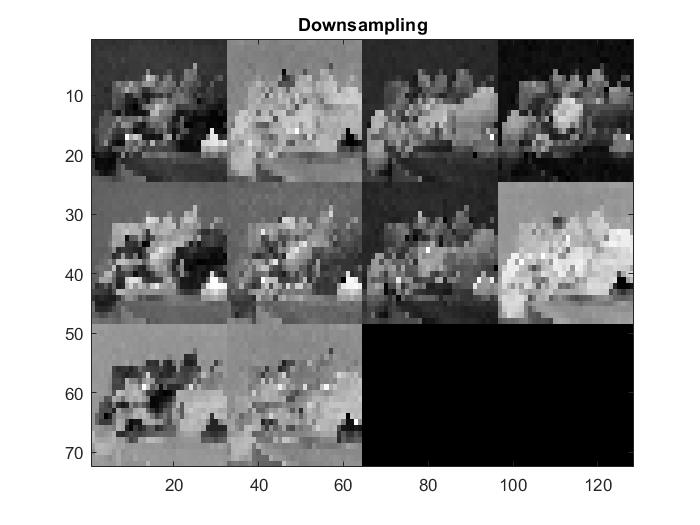

y_ds = vl_nnconv(x, w, [], 'stride', 16);
figure(3); clf; vl_imarraysc(y_ds); colormap gray; title('Downsampling');

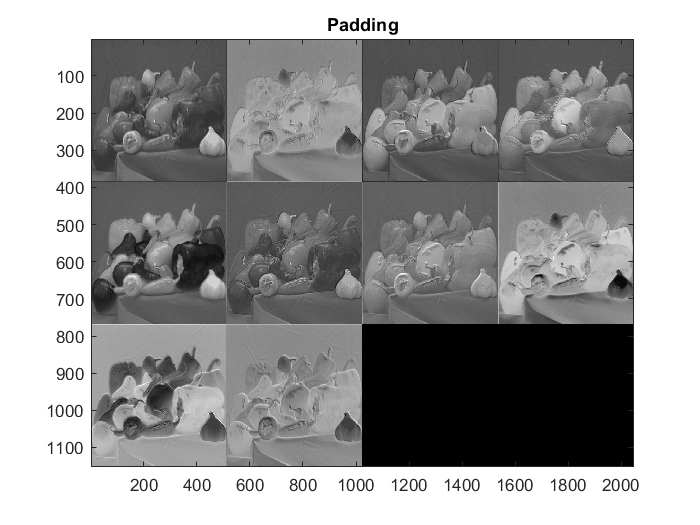


% Try (zero)padding
y_pad = vl_nnconv(x, w, [], 'pad', 2);
figure(4); clf; vl_imarraysc(y_pad); colormap gray; title('Padding');


% Your task: How does the size of y_pad differ from previous y? Can you explain why?
size(y_pad)

ans =    384   512    10


## Manually design a filter

## Your code starts here %%%

w2 = [0  1  0;
      1  -4  1;
      0  1  0];

## Your code stops here %%%

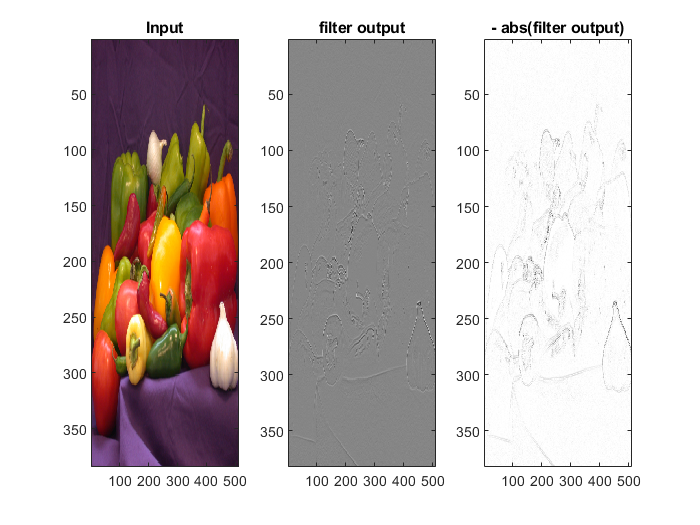

w2 = repmat(w2, [1, 1, 3]);

w2 = single(w2) ;  % single conversion
y_lap = vl_nnconv(x, w2, []) ;
figure(5) ; clf ; colormap gray ;

subplot(1,3,1) ; imagesc(x) ; title('Input');
subplot(1,3,2) ; imagesc(y_lap) ; title('filter output') ;
subplot(1,3,3) ; imagesc(-abs(y_lap)) ; title('- abs(filter output)');


% Your task: Currently the filter does nothing to the input image. 
%            Replace w2 with a 3x3 implementation of the Laplacian
%            operator. 
%            Why is the repmat function needed here?

%            The idea of repmat is that output is formed as an array
%            repetition of the original used array. Here repmat repeats the entries and 
%            and appends the values to the new variables with the previous dimensions.


%            Take a look at the result. 
%            What kind of a features does our filter extract?
%            The filter shows the outlines of items in the picture. It
%            shows
%            the outlines of areas in the picture where the is a large
%            shift in color.

## Non-linear gating (ReLU)

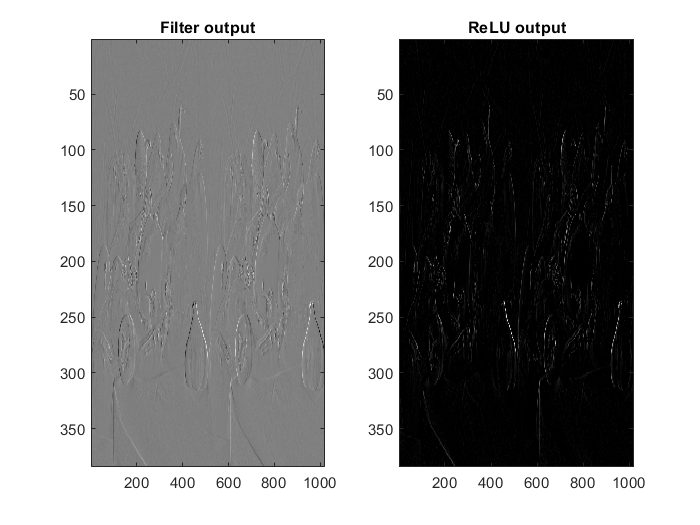

% Create a filter
w = single(repmat([1 0 -1], [1, 1, 3]));  
w = cat(4, w, -w); 

% Apply convolution
y = vl_nnconv(x, w, []);

% Non-linear activation function
z = vl_nnrelu(y);  % vl_nnrelu function implements ReLU

figure(6); clf; colormap gray;
subplot(1,2,1); vl_imarraysc(y); title('Filter output');
subplot(1,2,2); vl_imarraysc(z); title('ReLU output');


% Your task: Some of the functions in a CNN should be non-linear. Why?
% Without the non-linear functions the CNN can not make as complex
% decisions as it can with non-linear functions. It is usually very
% unlikely that the decision function we are modeling has a linear
% relationship with the input we are using. Concisely with a linear
% function relationship the apprixation does not rise and with non-linear
% it does.

## Pooling

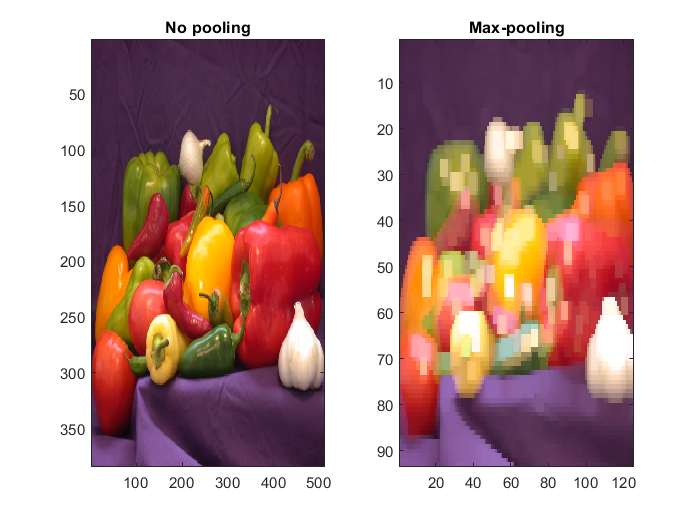

y = vl_nnpool(x, 15, 'Stride', 4) ;  % max pooling with a square filter of size 15
figure(7) ; clf ;
subplot(1,2,1); imagesc(x); title('No pooling');
subplot(1,2,2); imagesc(y); title('Max-pooling');


% Your task: Compare the result of max-pooling to the original.
%            What is the effect of max-pooling? 
%            What does the 'Stride' parameter do?

## Implementing a small CNN and optimizing with SGD

% 1. Start by running the algorithm without any pre-processing.
%    The blue lines in the histograms of scores represent classification 
%    thresholds, where values are either classifed as positive hits 
%    (those belonging to blobs) or negative hits. Values between these two 
%    thresholds are ignored.

%    How would the histograms set in an ideal case?
%    In an ideal case the histograms would set on the blue lines below 0 and
%    over 1.

%    What is the result here compared to the ideal case?
%    The classification thresholds do not classify optimally. Some sample
%    point are classified wrongly.


% 2. Train the tiny CNN by first smoothing the input image and subtracting 
%    the median value in preprocessing. Use the imsmooth function 
%    (defined in imsmooth.m) with the sigma value of 3 for smoothing.
%    The learned filter should resemble the discretisation of a well-known differential operator. 
%    Which one?
%    Edge detection filter


% 3. Try doubling the learning rate.
%    What is the effect of having too high of a learning rate?
% 
%    The model will converge too quickly and the final weigths aren't
%    optimal.
%
%    Restore the learning rate and set momentum to 0.
%    How does this differ from the previous with the same learning rate?

%    What is the benefit of using momentum?

%    Momentum means when we add the exponentially weighted average of the prior weight updates 
%    to the weights when they are updated. Momentum accelerates the
%    learning as it can make it faster to a better weight set.
%


% Load an image
im = rgb2gray(im2single(imread('data/dots.jpg'))) ;

% Compute the location of black blobs in the image
[pos,neg] = extractBlackBlobs(im) ;

fig = figure('Name','test', 'Position', [0,0,1000,600]);


% Pre-processing

## Your code starts here %%%

im = imsmooth(im,3);
im = im - median(im(:));

## Your code ends here %%%

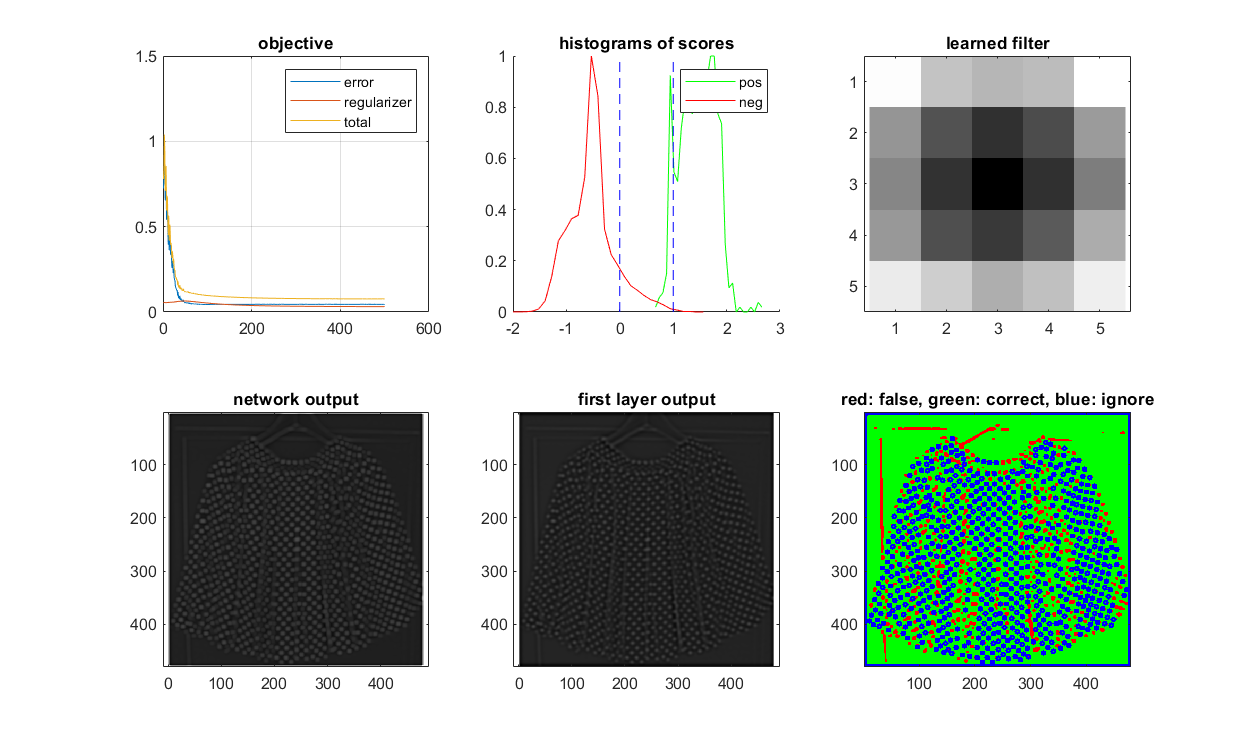

% Learning with stochastic gradient descent (SGD)

% SGD parameters:
% - numIterations: maximum number of iterations
% - rate: learning rate
% - momentum: momentum rate
% - shrinkRate: shrinkage rate5(or coefficient of the L2 regulariser)
% - plotPeriod: how often to plot

numIterations = 500 ;
rate = 5 ;
momentum = 0.9 ;
shrinkRate = 0.0001 ;
plotPeriod = 10 ;

% Initial CNN parameters:
w = 10 * randn(5, 5, 1) ;
w = single(w - mean(w(:))) ;
b = single(0) ;

% Create pixel-level labes to compute the loss
y = zeros(size(pos),'single') ;
y(pos) = +1 ;
y(neg) = -1 ;

% Initial momentum
w_momentum = zeros('like', w) ;
b_momentum = zeros('like', b) ;

% SGD with momentum
for t = 1:numIterations

  % Forward pass
  res = tinycnn(im, w, b) ;

  % Loss
  z = y .* (res.x3 - 1) ;

  E(1,t) = ...
    mean(max(0, 1 - res.x3(pos))) + ...
    mean(max(0, res.x3(neg))) ;
  E(2,t) = 0.5 * shrinkRate * sum(w(:).^2) ;
  E(3,t) = E(1,t) + E(2,t) ;

  dzdx3 = ...
    - single(res.x3 < 1 & pos) / sum(pos(:)) + ...
    + single(res.x3 > 0 & neg) / sum(neg(:)) ;

  % Backward pass
  res = tinycnn(im, w, b, dzdx3) ;

  % Update momentum
  w_momentum = momentum * w_momentum + rate * (res.dzdw + shrinkRate * w) ;
  b_momentum = momentum * b_momentum + rate * 0.1 * res.dzdb ;

  % Gradient step
  w = w - w_momentum ;
  b = b - b_momentum ;
  
  % Plots
  if mod(t-1, plotPeriod) == 0 || t == numIterations
    fp = res.x3 > 0 & y < 0 ;
    fn = res.x3 < 1 & y > 0 ;
    tn = res.x3 <= 0 & y < 0 ;
    tp = res.x3 >= 1 & y > 0 ;
    err = cat(3, fp|fn , tp|tn, y==0) ;
   
    set(0, 'currentfigure', fig); clf;
    colormap gray ;

    subplot(2,3,1) ;
    plot(1:t, E(:,1:t)') ;
    grid on ; title('objective') ;
    ylim([0 1.5]) ; legend('error', 'regularizer', 'total') ;

    subplot(2,3,2) ; hold on ;
    [h,x]=hist(res.x3(pos(:)),30) ; plot(x,h/max(h),'g') ;
    [h,x]=hist(res.x3(neg(:)),30) ; plot(x,h/max(h),'r') ;
    plot([0 0], [0 1], 'b--') ;
    plot([1 1], [0 1], 'b--') ;
    xlim([-2 3]) ;
    title('histograms of scores') ; legend('pos', 'neg') ;

    subplot(2,3,3) ;
    vl_imarraysc(w) ;
    title('learned filter') ; axis equal ;

    subplot(2,3,4) ;
    imagesc(res.x3) ;
    title('network output') ; axis equal ;

    subplot(2,3,5) ;
    imagesc(res.x2) ;
    title('first layer output') ; axis equal ;

    subplot(2,3,6) ;
    image(err) ;
    title('red: false, green: correct, blue: ignore') ;

    if verLessThan('matlab', '8.4.0')
      drawnow ;
    else
      drawnow expose ;
    end
  end
end